# Visualization of the regularization parameter selection on the L-curve

#### Author: Luis Fabregas

This quick tutorial will show how to construct the so-called L-curve for the selection of the optimal regularization parameter.

## Simulating a dipolar signal

Let's start by simulating a simple dipolar signal with some background and noise arising from a Gaussian distance distribution.

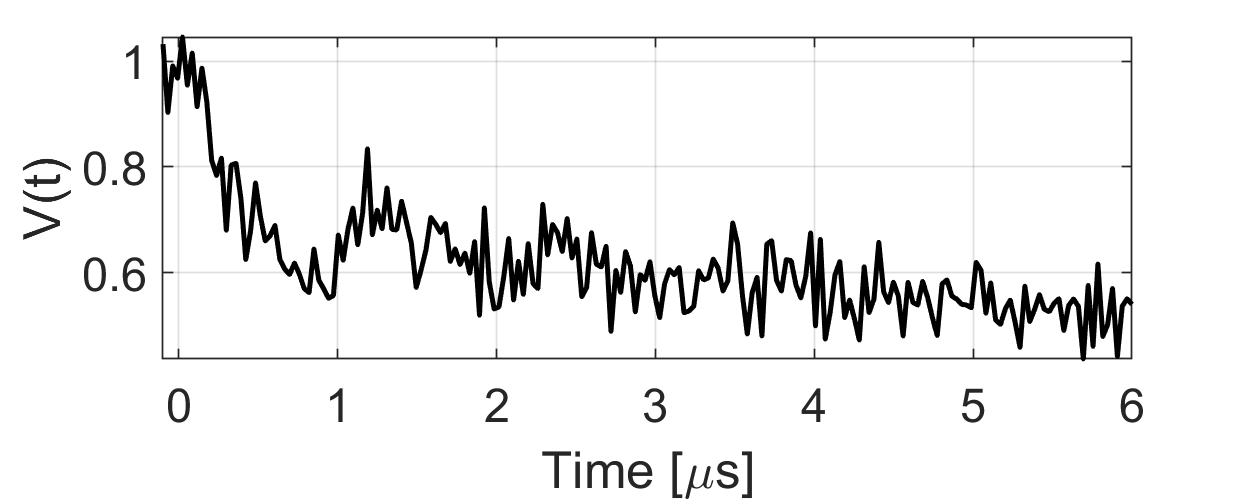

clear,clc,clf

%Prepare the signal components
t = linspace(-0.1,6,200);
r = linspace(2,8,200);
B = td_strexp(t,[0.05 2.9]);
P = rd_onegaussian(r,[4 0.2]);
lam = 0.3;

%Simulate the signal
V = dipolarsignal(t,r,P,'moddepth',lam,'background',B,'noiselevel',0.05);

%Plot
figure('position',[0 0 500 200])
plot(t,V,'k','Linewidth',1.5)
set(gca,'fontsize',14)
axis tight, grid on
xlabel('Time [\mus]'),ylabel('V(t)')

## Optimizing the regularization parameter

The first step is to choose the optimal regularization parameter using the `selregparam` function. In this case we want to compare the Akaike information criterion (AIC), Bayesian information criterion (BIC), Mallow's CL-method (MCL), generalized maximum likelihood (GML) and L-curve radius (LR) selection methods. The `selregparam `first output argument will return an array containing the optimal values for each of the input methods. 

In order to construct the L-curve we require the third to fitfth output arguments. The `alphas `variable contains all the evaluated regularization parameter values, and the `Res` `and Pen` contain the penalty and residual terms.

%Generate the appropiate dipolar kernel
KB = dipolarkernel(t,r,lam,B);

%Get the optimal regularization parameters for Tikhonov regularization
[alpha,~,alphas,Res,Pen] = selregparam(V,KB,r,'tikh',{'aic','gml','lr'});

## Constructing the L-curve

With all components in hand we can construct the L-curve. Since the L-curve is obtained from a log-log plot of the residual vs penalty terms we can easily construct them from the outputs of `selregparam.`

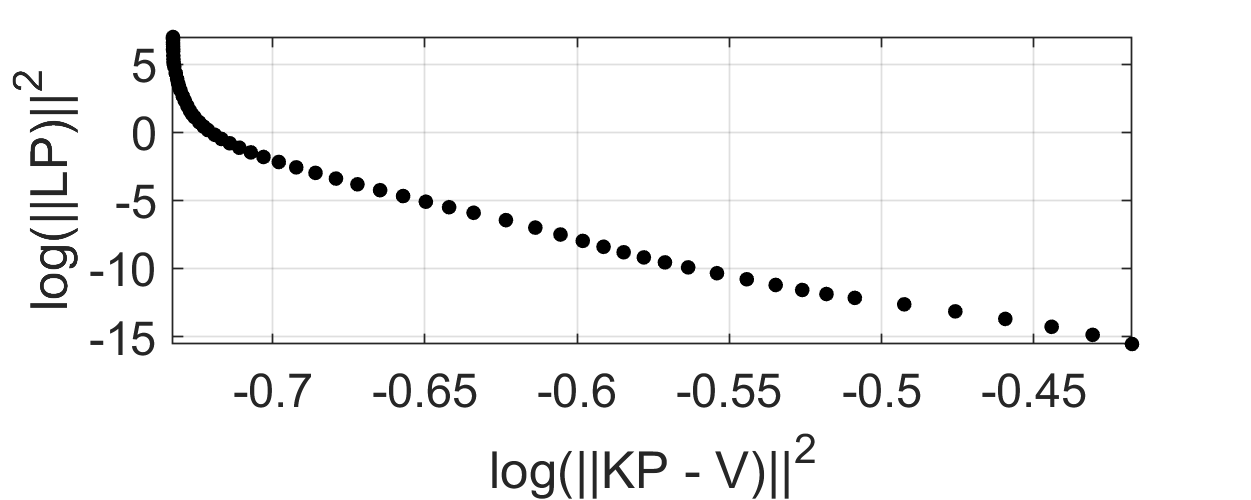

%Construct the vector of the L-curve
logRes = log(Res.^2);
logPen = log(Pen.^2);

%Plot the L-curve
figure('position',[0 0 500 200])
clf,hold on
plot(logRes,logPen,'k.','MarkerSize',15)
grid on,axis tight, box on
xlabel('log(||KP - V)||^2')
ylabel('log(||LP)||^2')
set(gca,'FontSize',14)

## Comparing selection methods on the L-curve

Finally we can compare the optimal values selected by the different selection methods on the L-curve.

 To do this we need to locate the optimal values of each method on the array `alphas.` This way we can obtain the indices of the optimal parameters and plot them on the L-curve.

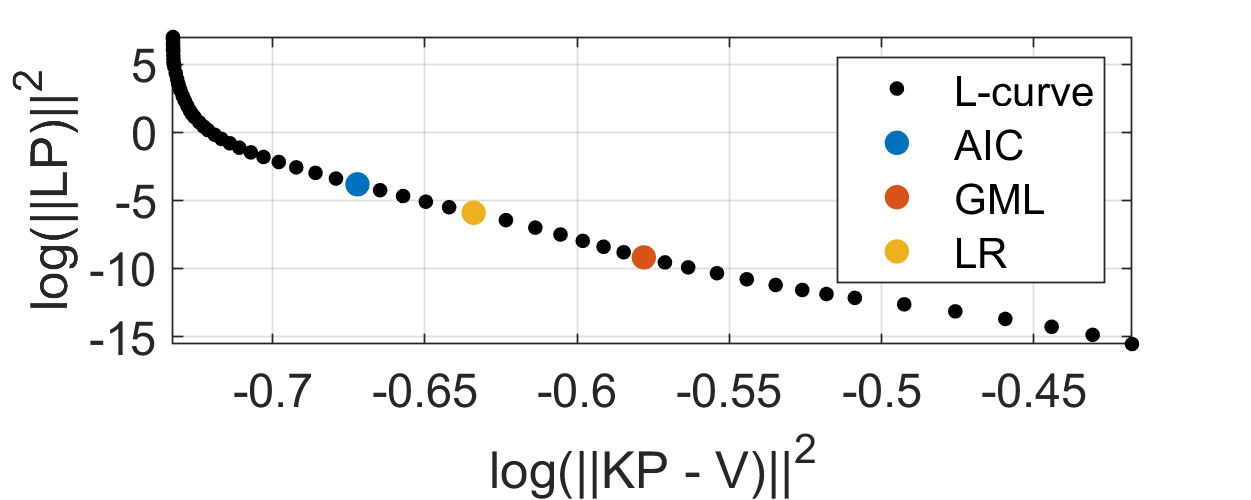


%Find the positions of the different optimal regularizfation parameters 
%on the L-curve
AICidx = alphas==alpha(1);
GMLidx = alphas==alpha(2);
LRidx  = alphas==alpha(3);

%Plot the L-cruve and the optimal parameters
plot(logRes(AICidx),logPen(AICidx),'.','MarkerSize',25)
plot(logRes(GMLidx),logPen(GMLidx),'.','MarkerSize',25)
plot(logRes(LRidx),logPen(LRidx),'.','MarkerSize',25)
legend('L-curve','AIC','GML','LR')